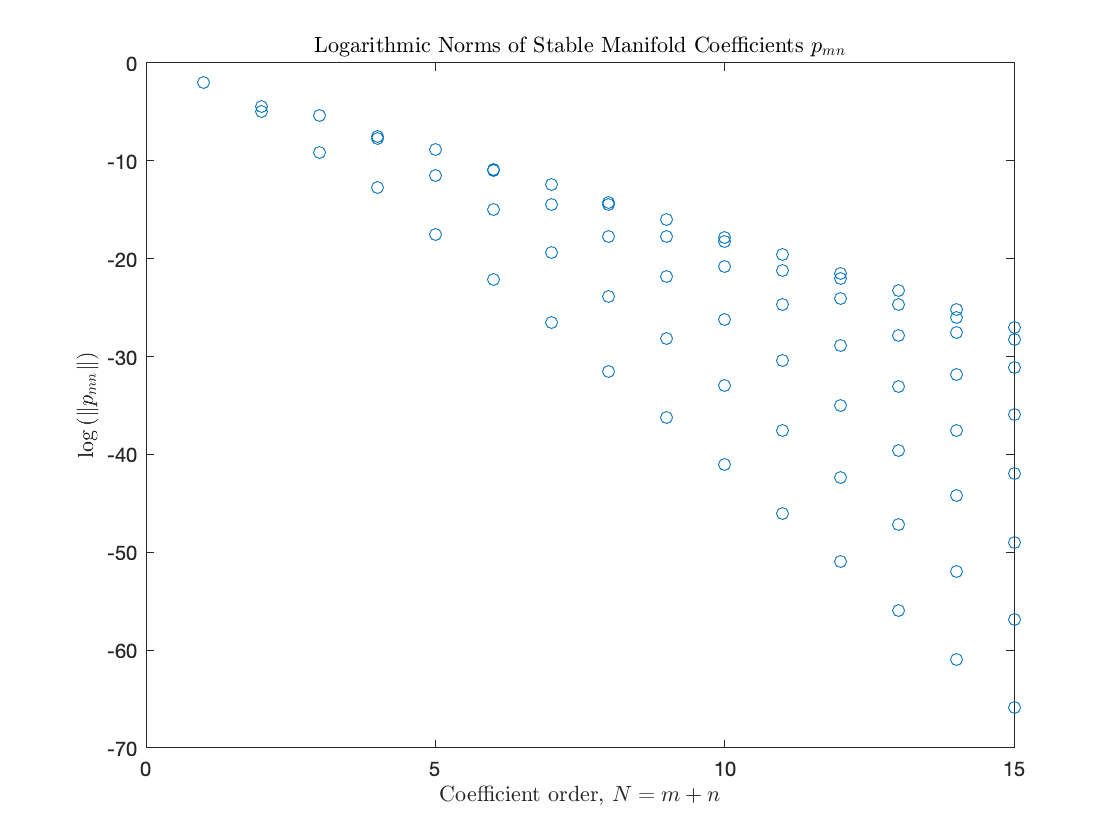

params.mu = .1;
params.nu = 1.6;
params.scale = 1/7;

order = 15;
params.mfld.order = order;

params = get_mflds(params);
coeff = params.stable.coeffs;

normorder=zeros(order+1,order+1);
plotpoints=[];
suborder=1;
while suborder<order+1
    for i=0:suborder
        for j = suborder-i
            vec=zeros(1,4);
            for k=1:4
                vec(k)=coeff(i+1,j+1,k);
            end
            
            normpoint=norm(vec);
            normorder(i+1,j+1)=normpoint;
            point=[suborder;normpoint];
            plotpoints=[plotpoints,point];
        end
    end
    suborder=suborder+1;
end

h = figure;
plot(plotpoints(1,:), log(plotpoints(2,:)),'o');
xlabel('Coefficient order, $N = m + n$', Interpreter = 'latex')
ylabel('$\log\left(\|p_{mn}\|\right)$', Interpreter = 'latex')
title('Logarithmic Norms of Stable Manifold Coefficients $p_{mn}$', Interpreter = 'latex')
exportgraphics(h,'stable_coeff_decay.pdf')

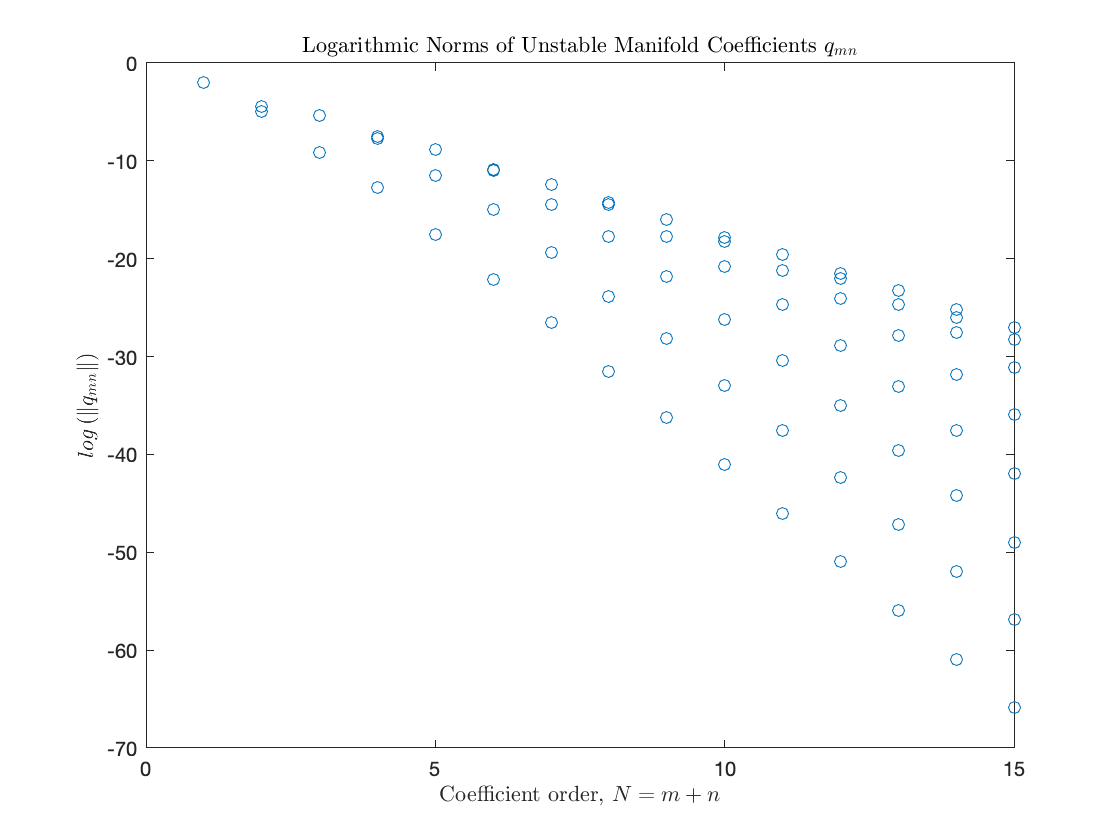


coeff = params.unstable.coeffs;
normorder=zeros(order+1,order+1);
plotpoints=[];
suborder=1;
while suborder<order+1
    for i=0:suborder
        for j = suborder-i
            vec=zeros(1,4);
            for k=1:4
                vec(k)=coeff(i+1,j+1,k);
            end
            
            normpoint=norm(vec);
            normorder(i+1,j+1)=normpoint;
            point=[suborder;normpoint];
            plotpoints=[plotpoints,point];
        end
    end
    suborder=suborder+1;
end

figure
plot(plotpoints(1,:), log(plotpoints(2,:)),'o');
xlabel('Coefficient order, $N = m + n$', Interpreter = 'latex')
ylabel('$log\left(\|q_{mn}\|\right)$', Interpreter = 'latex')
title('Logarithmic Norms of Unstable Manifold Coefficients $q_{mn}$', Interpreter = 'latex')

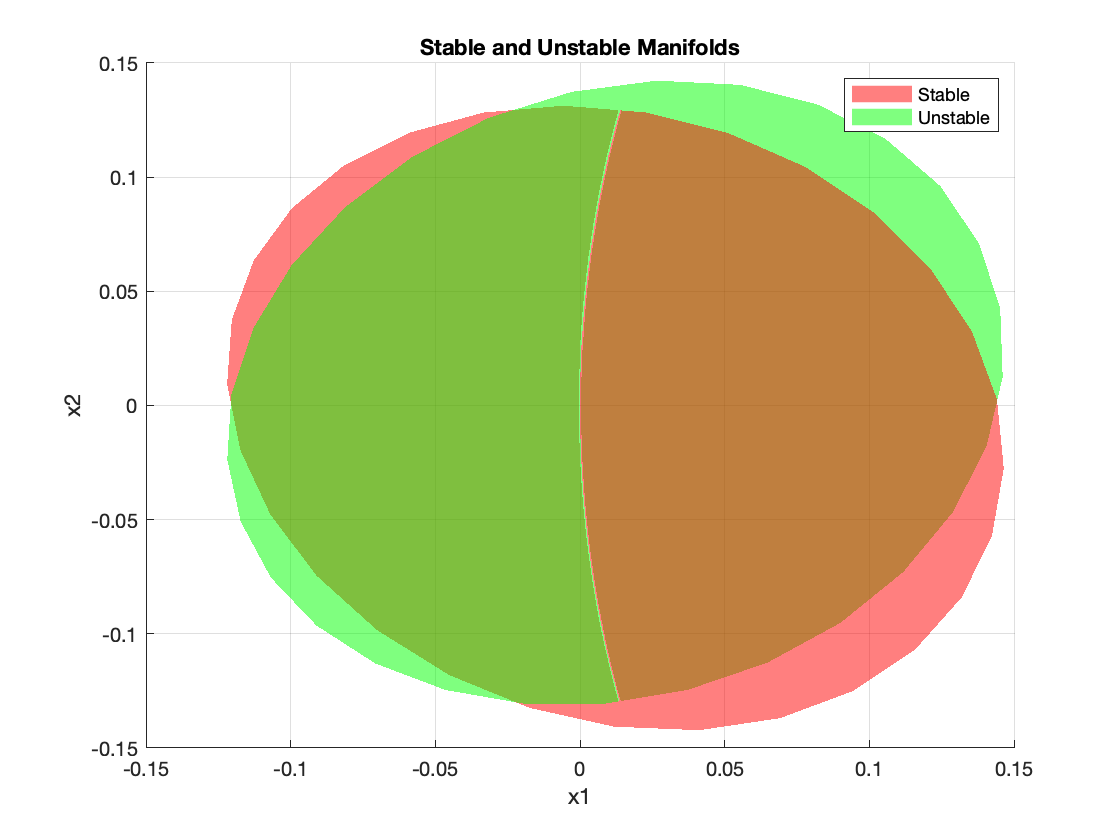

s_points=mfld_points(params.stable.coeffs, params);
u_points=mfld_points(params.unstable.coeffs, params);

figure
grid on 
hold on
surf(s_points(:,:,1),s_points(:,:,2),s_points(:,:,4), 'FaceColor','r', 'FaceAlpha',0.5, 'EdgeColor','none');  
xlabel('x1');
ylabel('x2');
zlabel('x4');
surf(u_points(:,:,1),u_points(:,:,2),u_points(:,:,4), 'FaceColor','g', 'FaceAlpha',0.5, 'EdgeColor','none');  
title('Stable and Unstable Manifolds');
legend('Stable', 'Unstable');
hold off

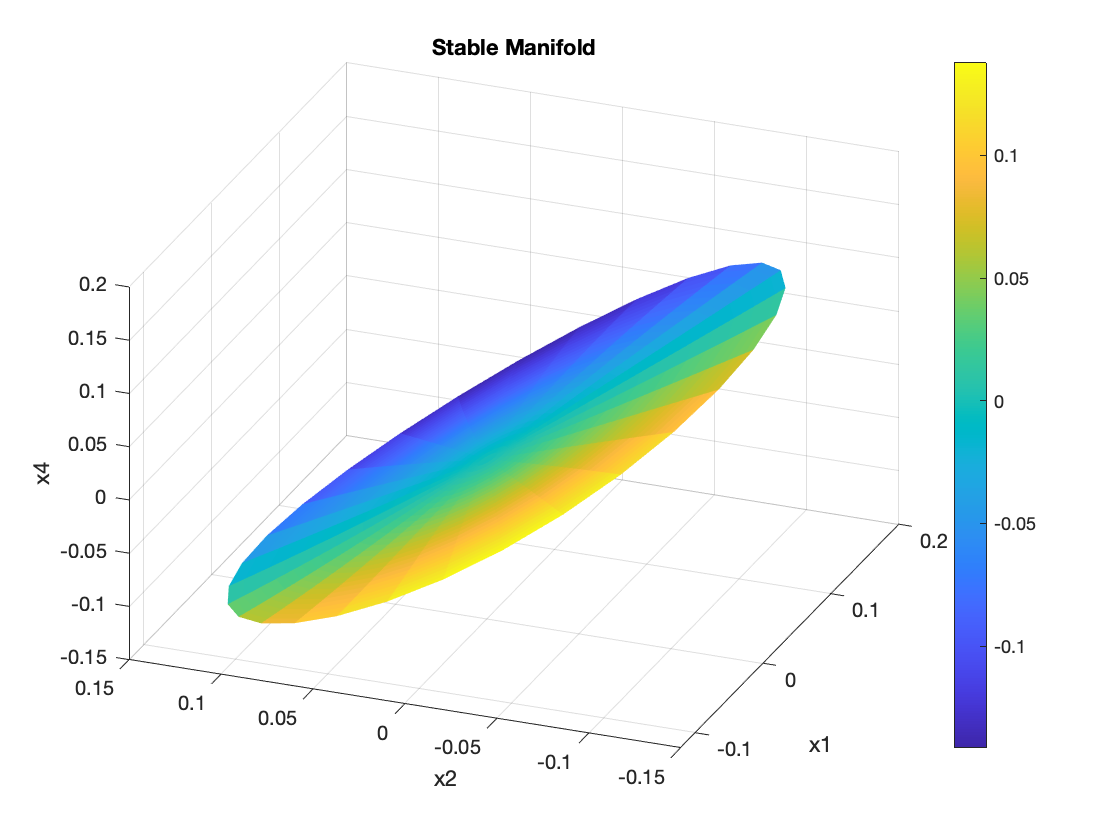

h = figure;
grid on 
surf(s_points(:,:,1),s_points(:,:,2),s_points(:,:,4), s_points(:,:,3), 'EdgeColor','none');  
colorbar;
xlabel('x1');
ylabel('x2');
zlabel('x4');
title('Stable Manifold');
view([-68.462 32.862])
exportgraphics(h,'stable_mfld.pdf')

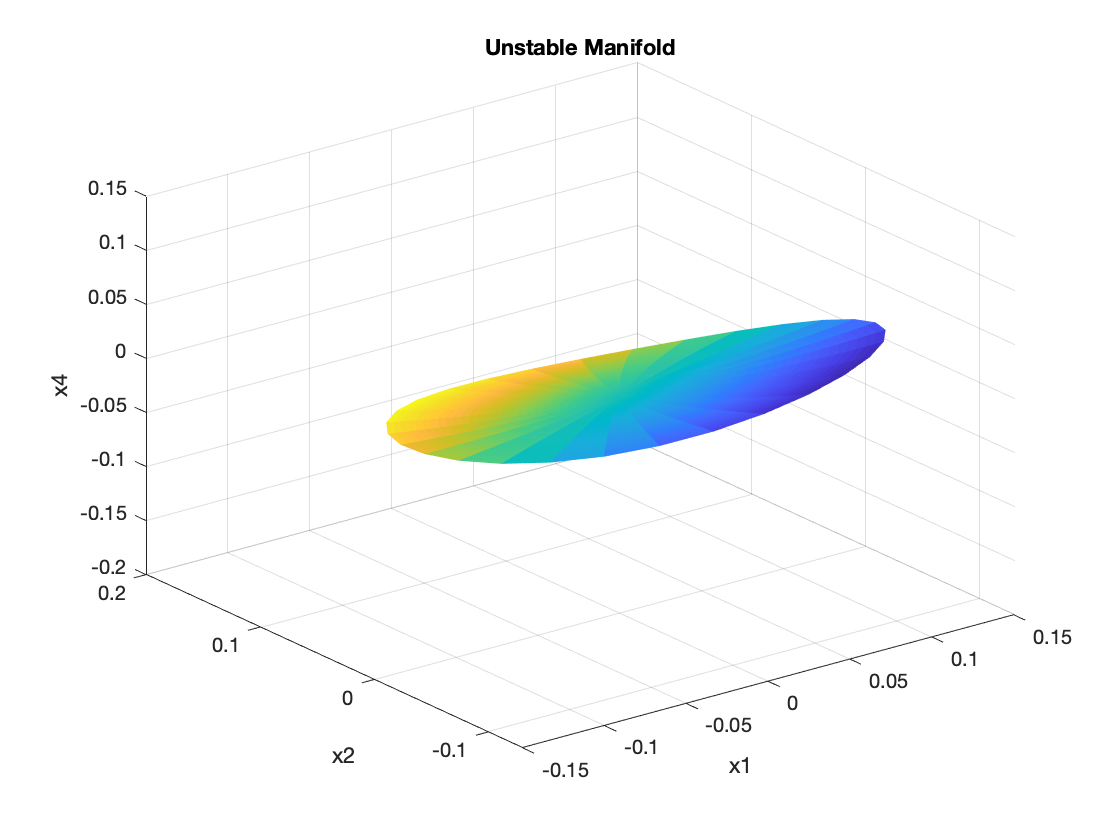




figure 
grid on 
surf(u_points(:,:,1),u_points(:,:,2),u_points(:,:,4),u_points(:,:,3), 'EdgeColor','none');  
xlabel('x1');
ylabel('x2');
zlabel('x4');
title('Unstable Manifold');

order = 3

order = 3

new_coeff = zeros(order + 1, order + 1, 4);
for i = 1:order + 1
    for j = 1:order + 1
        disp(i)
        disp(j)
        test = round(params.stable.coeffs(i,j,:), 3);
        test = reshape(test, [1,4]);
        disp(test);
        new_coeff(i,j,:) = test;
    end
end

     1


     1


     0     0     0     0


     1


     2


   0.0310 + 0.0620i  -0.0670 + 0.0210i  -0.0110 - 0.0710i   0.0740 + 0.0000i


     1


     3


   0.0000 + 0.0010i  -0.0010 + 0.0000i   0.0000 - 0.0030i   0.0060 + 0.0020i


     1


     4


     0     0     0     0


     2


     1


   0.0310 - 0.0620i  -0.0670 - 0.0210i  -0.0110 + 0.0710i   0.0740 + 0.0000i


     2


     2


    0.0120   -0.0040    0.0010         0


     2


     3


  -0.0020 - 0.0010i   0.0020 - 0.0010i   0.0000 + 0.0020i  -0.0030 - 0.0010i


     2


     4


     0     0     0     0


     3


     1


   0.0000 - 0.0010i  -0.0010 + 0.0000i   0.0000 + 0.0030i   0.0060 - 0.0020i


     3


     2


  -0.0020 + 0.0010i   0.0020 + 0.0010i   0.0000 - 0.0020i  -0.0030 + 0.0010i


     3


     3


     0     0     0     0


     3


     4


     0     0     0     0


     4


     1


     0     0     0     0


     4


     2


     0     0     0     0


     4


     3


     0     0     0     0


     4


     4


     0     0     0     0



for i = 1:order + 1
    for j = 1:order + 1
        disp(i)
        disp(j)
        test = round(params.unstable.coeffs(i,j,:), 2);
        test = reshape(test, [1,4]);
        disp(test);
    end
end

     1


     1


     0     0     0     0


     1


     2


  -0.0300 + 0.0600i  -0.0700 - 0.0200i   0.0100 - 0.0700i   0.0700 + 0.0000i


     1


     3


         0         0         0   -0.0100


     1


     4


     0     0     0     0


     2


     1


  -0.0300 - 0.0600i  -0.0700 + 0.0200i   0.0100 + 0.0700i   0.0700 + 0.0000i


     2


     2


    0.0100         0         0         0


     2


     3


     0     0     0     0


     2


     4


     0     0     0     0


     3


     1


         0         0         0   -0.0100


     3


     2


     0     0     0     0


     3


     3


     0     0     0     0


     3


     4


     0     0     0     0


     4


     1


     0     0     0     0


     4


     2


     0     0     0     0


     4


     3


     0     0     0     0


     4


     4


     0     0     0     0
